clear;
addpath('./lib');
altitude_waypoints = [  0,  0;
                        10, 10;
                        50, 10;
                        60, 0   ];

m_inert = 275*0.453592;

[optimal_mass, guess_history] = optimizeMass(altitude_waypoints, m_inert, 1.3*m_inert);

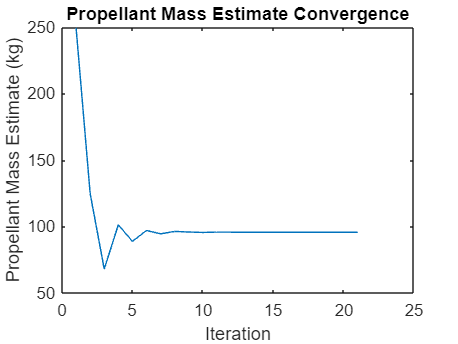

figure;
plot(guess_history)
title("Propellant Mass Estimate Convergence");
xlabel("Iteration");
ylabel("Propellant Mass Estimate (kg)");


fprintf("Final Propellant Mass estimate: %.3f kg\n", guess_history(end));

Final Propellant Mass estimate: 95.683 kg


fprintf("Final Total Mass estimate: %.3f kg\n", m_inert + guess_history(end));

Final Total Mass estimate: 220.420 kg
